clearvars;

% Init param
M = 2;
[x, q] = PAM_generator(M); % for equiprobable symbols

N = 20;
[z, w] = GaussHermite_Locations_Weights(N);
SNR = 7;

rho = 0;
max_rho = 1.0;
delta = 0.001;
E0_values = [];  % Pel display
rho_values = []; % Pel display

maxE0 = -Inf;
best_rho = -1;

% E0 computation
tic; % Time start -----------------------------------------------
% Calcular E0 en función de rho
while rho <= max_rho
    E0_i = E0(rho, N, q, x, w, z, SNR);
    E0_values = [E0_values, E0_i];      % Pel display
    rho_values = [rho_values, rho];     % Pel display                
    if E0_i > maxE0
        maxE0 = E0_i;
        best_rho = rho;
    end
    rho = rho + delta;
end
elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 0.003263 segons


% Display
disp("Rho for which E0 is max:");

Rho for which E0 is max:


disp(best_rho);

   0.999000000000001



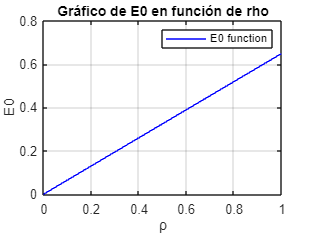


% Gràfica d'E0 respecte rho
plot(rho_values, E0_values, 'b', 'DisplayName', 'E0 function');
xlabel('ρ');
ylabel('E0');
title('Gráfico de E0 en función de rho');
legend;
grid on;

% Per E0(1)
tic;
E = E0(1, N, q, x, w, z, SNR);
elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 0.0049936 segons


disp(E)

   0.998685031876361

